%Euler integration method of an RL circuit

clear all;  
close all;  
clc;        


% Circuit Values RL
r=0.1        

r = 0.1000

L=3.0e-3     

L = 0.0030


% initial conditions
thetapunt=0   % Initial position

thetapunt = 0

i=0 % Initial current

i = 0

t=0 % Initial time

t = 0


% Parameter definition (simulation) - duration and step
tfi=0.18 % Duration

tfi = 0.1800

Delta=0.5e-3  % Integration step

Delta = 5.0000e-04

tgrao=0     % Input step

tgrao = 0

%Integration
n=1  % Starting the counter

n = 1

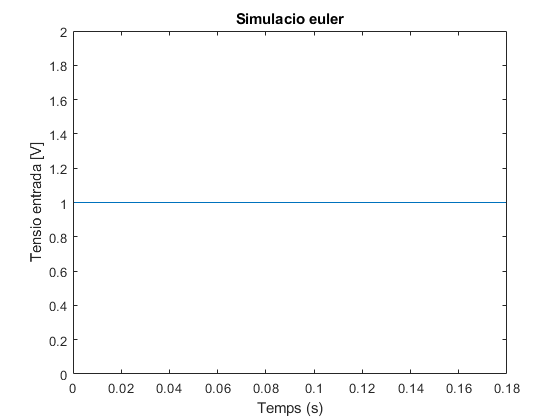

while (n+1)*Delta<tfi

    %Definition of the step
    if (n+1)*Delta<tgrao
       u=0;
       else 
       u=1;
    end
    
    
    %Typical state space
    %x(t)=Ax(t)+Bu(t)
    %y(t)=Cx(t)
    
    % Euler method
    %x(t+X)=x(t)+Ax(t)+Bu(t)
    %y(t)=Cx(t)
    i(n+1)=i(n)+(-r/L*i(n)+1/L*u)*Delta;
    t(n)=Delta*n;
    entrada(n)=u;
    n=n+1;

end
% Last iteration
entrada(n)=entrada(n-1);
t(n)=Delta*n;

% Results
figure()
plot(t,entrada)
xlabel('Temps (s)')
ylabel('Tensio entrada [V]')
title('Simulacio euler')

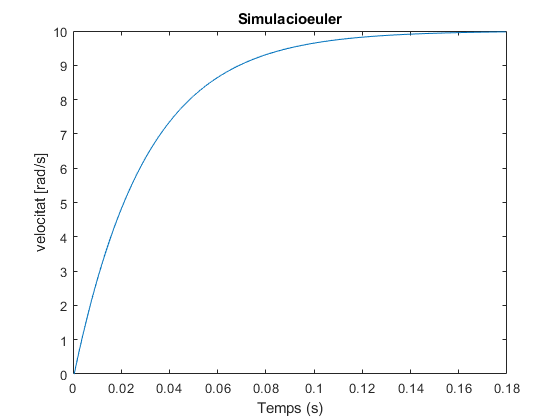


figure()
plot(t,i)
xlabel('Temps (s)')
ylabel('velocitat [rad/s]')
title('Simulacioeuler')